## Problem 2

M0_deg = 45;
M0 = deg2rad(M0_deg)

M0 = 0.7854

rp = 15300;
ra = 61000;
mu = 398600.4415;

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

### Part a)

a = (rp+ra)/2

a = 38150

energy = -mu/(2*a)

energy = -5.2241

e = 1- rp/a

e = 0.5990

p = a*(1-e^2)

p = 2.4464e+04

period = 2*pi*sqrt(a^3/mu), periodhr = period/3600

period = 7.4157e+04

periodhr = 20.5992



E0 = M0;
for m = 1:100
    temp = 2/m*bessel(m,e)*sin(m*M0);
    E0 = E0 + temp;
end
E0

E0 = 1.3136

for n = 1:10
    E0 = E0 - (E0 - e*sin(E0) - M0)/(1 - e*cos(E0));
end
E0

E0 = 1.3726

M_check = E0 - e*sin(E0)

M_check = 0.7854

th0 = 2*atan(sqrt((1+e)/(1-e))*tan(E0/2))

th0 = 2.0441

th0_deg = rad2deg(th0)

th0_deg = 117.1182


r0_mag = p / (1+e*cos(th0))

r0_mag = 3.3651e+04

v0_mag = sqrt(mu*(2/r0_mag-1/a))

v0_mag = 3.6389

n = sqrt(a^3/mu)

n = 1.1802e+04

dt0 = M0*n

dt0 = 9.2696e+03

dt0_hr = dt0/3600

dt0_hr = 2.5749

th0dot = sqrt(mu*p)/r0_mag^2

th0dot = 8.7202e-05

gamma0 = acos(r0_mag*th0dot/v0_mag)

gamma0 = 0.6327

gamma0_deg = rad2deg(gamma0) 

gamma0_deg = 36.2532

### Part b)

r0 = r0_mag * [cos(th0) sin(th0)]

r0 = 	1.0e+04 *

   -1.5339    2.9952


r0_polar = r0_mag * [1 0]

r0_polar = 	1.0e+04 *

    3.3651         0


v0_polar = v0_mag * [sin(gamma0) cos(gamma0)]

v0_polar =     2.1519    2.9345


ICR = [cos(th0) -sin(th0); sin(th0) cos(th0)]

ICR =    -0.4558   -0.8901
    0.8901   -0.4558


v0 = (ICR* v0_polar')'

v0 =    -3.5928    0.5777


### Part c)

dt = 400 * 60

dt = 24000

M = sqrt(mu/a^3)*dt + M0

M = 2.8189

M_deg = rad2deg(M)

M_deg = 161.5094

E = M;
for m = 1:100
    temp = 2/m*bessel(m,e)*sin(m*M);
    E = E + temp;
end
E

E = 2.9266

for n = 1:10
    E = E - (E - e*sin(E) - M)/(1 - e*cos(E));
end
E

E = 2.9392

M_check = E - e*sin(E)

M_check = 2.8189

th = 2*atan(sqrt((1+e)/(1-e))*tan(E/2))

th = 3.0400

th_deg = rad2deg(th) 

th_deg = 174.1787


dE = E - E0

dE = 1.5666

f = 1 - a/r0_mag * (1-cos(dE))

f = -0.1289

g = dt - sqrt(a^3/mu) * (dE - sin(dE))

g = 1.7312e+04

r_mag = p / (1+e*cos(th)), v_mag = sqrt(mu*(2/r_mag-1/a))

r_mag = 6.0534e+04

v_mag = 1.6496

fdot = -sqrt(mu/a^3)*a^2/(r_mag*r0_mag) * sin(dE)

fdot = -6.0536e-05

gdot = 1 - a/r_mag * (1 - cos(dE))

gdot = 0.3724

### Part d)

r_r0v0 = [f/r0_mag g/v0_mag]

r_r0v0 = 	1.0e+03 *

   -0.0000    4.7576


v_r0v0 = [fdot/r0_mag gdot/v0_mag]

v_r0v0 =    -0.0000    0.1023



f_dth = 1 - r_mag/p * (1 - cos(th - th0))

f_dth = -0.1289

g_dth = r_mag * r0_mag / sqrt(mu*p) * sin(th-th0)

g_dth = 1.7312e+04


r_I = f*r0 + g*v0

r_I = 	1.0e+04 *

   -6.0222    0.6140


v_I = fdot*r0 + gdot*v0

v_I =    -0.4094   -1.5980


### Part e)

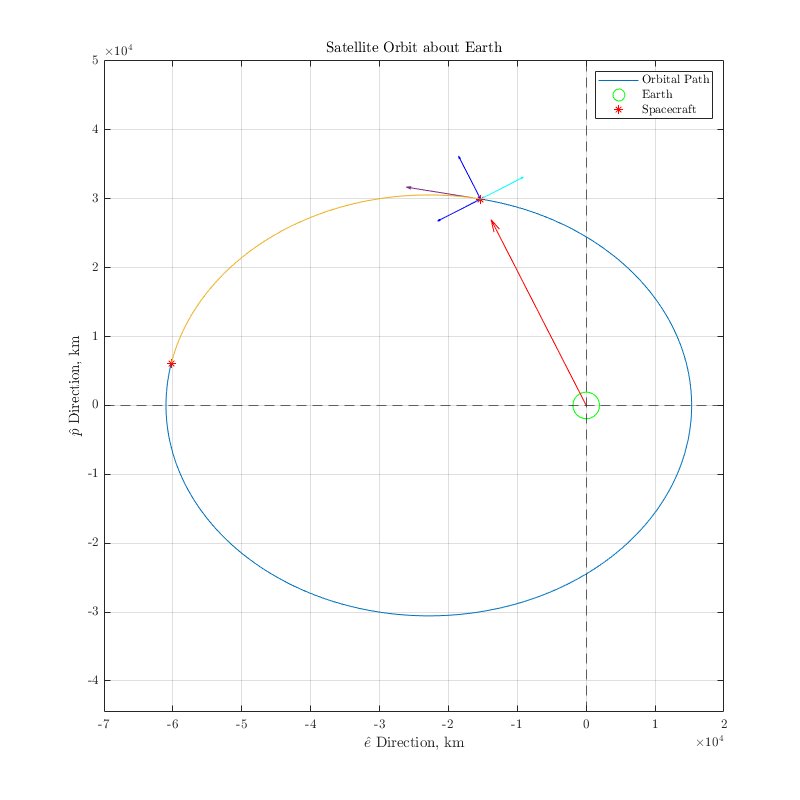

th_plot = linspace(0,2*pi,2^10);
r_plot = p./(1+e*cos(th_plot)); rx = r_plot.*cos(th_plot); ry = r_plot.*sin(th_plot);
plot(rx,ry)
hold on
plot(0,0,'go','markersize',20)
plot(r0(1),r0(2),'r*')
plot(r_I(1),r_I(2),'r*')
grid on
quiver(r0(1),r0(2),cos(th0),sin(th0),7e3,'b')% r hat 
quiver(r0(1),r0(2),-sin(th0),cos(th0),7e3,'b')% th hat
quiver(r0(1),r0(2),sin(th0),-cos(th0),7e3,'c')% local horizon
quiver(r0(1),r0(2),v0(1),v0(2),3e3,'color','#7E2F8E') % v0 vector
quiver(r0(1),r0(2),'r') % r0 vector
th_plot = linspace(th0,th,2^10);
r_plot = p./(1+e*cos(th_plot)); rx = r_plot.*cos(th_plot); ry = r_plot.*sin(th_plot);
plot(rx,ry)
xline(0,'--'),yline(0,'--')
set(gcf,'position',[0,0,1000,1000])
xlim([-7 2]*1e4)
ylim([-4 4]*1e4)
axis equal
xlabel('$\hat{e}$ Direction, km')
ylabel('$\hat{p}$ Direction, km')
legend('Orbital Path','Earth','Spacecraft','')
title('Satellite Orbit about Earth')

Function 1: Bessel function

function jm = bessel(m,e)
jm = 0;
    for n = 0:20
        jm = jm + (-1)^n * (m*e/2)^(n+m) / (factorial(n)*factorial(m+n));
    end
end